# Week 2 Assignment

**Kathia Coronado**

*Robotics Engineering Graduate Student, Worcester Polytechnic Institute, Worcester, Massachussets, kcoronado@wpi.edu*

### Introduction:

**Problem 1**

Problem 1, of Robot Modeling and Control Second Edition by Spong et al., gives a series of rotations in which a system has undergone. The rotations are performed about different frames and axes. Below is the sequence of rotations given by the problem statement, see figure 1.

- *Rotate by *$\phi$* about the world x-axis*

- *Rotate by *$\theta$* about the world z-axis*

- *Rotate by *$\varphi$* about the current x-axis*

- *Rotate by *$\alpha$* about the world z-axis*

**Figure 1** - Sequence of rotations given by the problem statement 

The objective of this report is to present the matrix product that will give the resulting rotation matrix. This will be achieved by explicitly displaying and describing each step taken towards achieving the desired rotation matrix. This will involve not only showing the associated formulas but also displaying a figure that illustrates the described rotation. Once the rotation matrix equation is derived, random values will be produced for all angle variables and the appropriate matrix product will be calculated.

**Problem 2**

The objective of problem 2 is to determine the homogeneous transformations, $H_1^0 ,H_2^0 ,\textrm{and}\;H_2^1$ for the diagram displayed in figure 2.13. It must also be shown that  $H_2^0 =H_1^0 H_2^1 \;$.

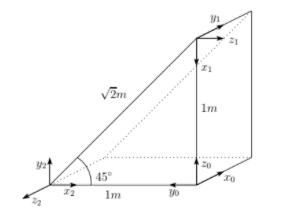

**Figure (2.13)** - Diagram for Problem 2-37

**Problem 3**

The objective of problem 3 is to analyze the behavior of Denso's HSR robot, figure 3, by drawing the end effector path in response to varying joint angle input and assessing that the path is within the range of motion described by the manufacture. It will be discussed if the MATLAB model of the robot produced in this report is comparable to the actual robot. 

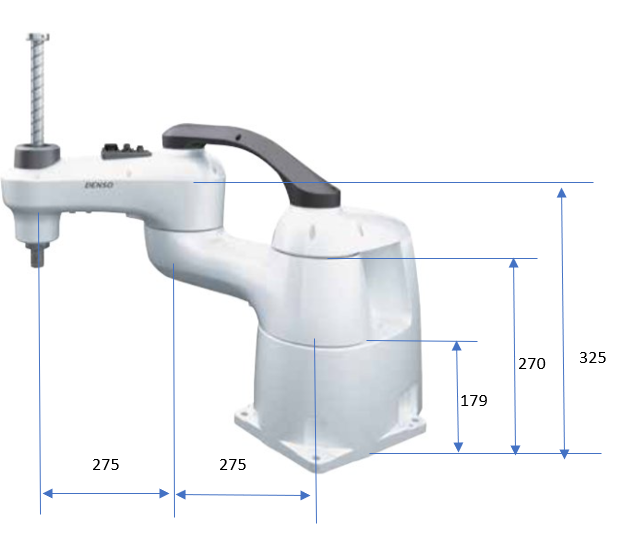

**Figure 3 **- Denso HSR series 480 mm robot with labeled assumed lengths 

### Methods and Materials:

**Problem 1**

Answer:

$\mathit{\mathbf{R}}={\mathit{\mathbf{R}}}_{\mathit{\mathbf{z}},\alpha } {\mathit{\mathbf{R}}}_{\mathit{\mathbf{z}},\theta } {\mathit{\mathbf{R}}}_{\mathit{\mathbf{x}},\phi } {\mathit{\mathbf{R}}}_{\mathit{\mathbf{x}},\varphi } =\left\lbrack \begin{array}{ccc}
\mathit{\mathbf{c}}\alpha  & -\mathit{\mathbf{s}}\alpha  & 0\\
\mathit{\mathbf{s}}\alpha  & \mathit{\mathbf{c}}\alpha  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
\mathit{\mathbf{c}}\theta  & -\mathit{\mathbf{s}}\theta  & 0\\
\mathit{\mathbf{s}}\theta  & \mathit{\mathbf{c}}\theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \mathit{\mathbf{c}}\phi  & -\mathit{\mathbf{s}}\phi \\
0 & \mathit{\mathbf{s}}\phi  & \mathit{\mathbf{c}}\phi 
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \mathit{\mathbf{c}}\varphi  & -\mathit{\mathbf{s}}\varphi \\
0 & \mathit{\mathbf{s}}\varphi  & \mathit{\mathbf{c}}\varphi 
\end{array}\right\rbrack$                       ** (1d)**

Problem 1 deals with composition of rotations, or the order in which successive rotation matrices should be multiplied to produce the correct rotation matrices. Composition of rotations involves knowing the difference between current frame and fixed or world frame rotations. When rotations are performed as a sequence of rotations about a fixed coordinate frame, rather than the successive current frames, they are called fixed frame rotations (1). World frame refers to the frame at the base of the manipulator robot; it is fixed. If a sequence of rotations is performed about the world coordinate frame, then the rotations are being performed relative to the fixed world frame. A current frame is the frame relative to which the rotation occurs (1). The current frame changes with each successive rotation.

The rules of composition of rotations state that if the rotation is performed about a fixed or world coordinate frame axis, then the previous rotations must be pre-multiplied by the described fixed frame rotations. Equation 2.23 from the textbook, displays the case where the second rotation,$R_2^1$ , is performed relative to the fixed frame, therefore the previous rotation,$R_1^0$ , is pre-multiplied by the second rotation. On the other hand, if the rotation is performed about a current coordinate frame axis then the previous multiplication should be post multiplied by the described current frame rotation. Equation 2.22 from the textbook, describes the case where the second rotation,$R_2^1$ , is performed relative to the current frame, therefore the previous rotation, $R_1^0$, is pos-tmultiplied by the second rotation.

$R_2^0 =R_1^0 R_2^1$                                                                                                                                         (2.22)

$R_2^0 =R_2^1 R_1^0$                                                                                                                                         (2.23)

The successive rotations given by the problem statement, displayed in figure 1, are all basic rotation matrices. The basic rotation matrix about the z axis by any angle theta is given by equation 2.3. The basic rotation matrix about the x axis by any angle theta is given by equation 2.7. The basic rotation matrix about the y axis by any angle theta is given by equation 2.8.

$R_{z,\theta}= \left[\matrix{ cos(\theta) & -sin(\theta) & 0 \cr sin(\theta)&cos(\theta) &0 \cr 0 & 0 & 1} \right]$                                                                                                             (2.3) 

$R_{x,\theta}= \left[\matrix{ 1 & 0 & 0 \cr 0&cos(\theta) &-sin(\theta) \cr 0 & sin(\theta) & cos(\theta) } \right]$                                                                                                             (2.7)

$R_{y,\theta}= \left[\matrix{ cos(\theta) & 0 & sin(\theta) \cr 0&1 &0 \cr -sin(\theta) &0) & cos(\theta) } \right]$                                                                                                            (2.8)

Using the definitions of current frame and fixed frame, the successive rotations given by the problem statement were classified. The subcomponents of equation 1 will display the steps to derive the  final rotation matrix for the system. The first rotation of the system was by an angle of $\phi$ about the world x-axis, $R_{x,\phi }$. Since this is the first rotation it does not make a difference if we post or pre multiply. The angle given by the problem for the rotation is inputted into equation 2.7. To make the notation clearer, *c* and *s* are used as the shorthand notation for *cos* and *sin.*  Equation 1a displays  the first rotation.  Figure 2a, displays what the first rotation would look like, $x_{1,} y_{1,} z_1$ represents the  new current frame.

$R=R_{x,\phi } =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & c\phi  & -s\phi \\
0 & s\phi  & c\phi 
\end{array}\right\rbrack$                                                                                                                 (1a)

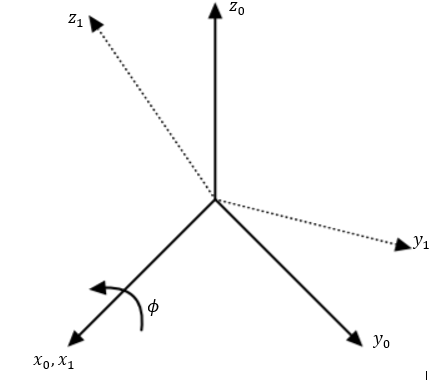

**Figure 2a** - Rotation by $\phi$ about the world x-axis

The second rotation is by an angle of $\theta$ about the world z-axis, $R_{z,\theta }$. Since the second rotation is about the world frame, the right-hand side of  equation 1a needs to be premultiplied by $R_{z,\theta }$, see equation 1b. Figure 2b, displays what the second rotation would look like, $x_{2,} y_{2,} z_2$ represents the  new current frame. 

$R=R_{z,\theta } R_{x,\phi } =\left\lbrack \begin{array}{ccc}
c\theta  & -s\theta  & 0\\
s\theta  & c\theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & c\phi  & -s\phi \\
0 & s\phi  & c\phi 
\end{array}\right\rbrack$                                                                                     (1b)

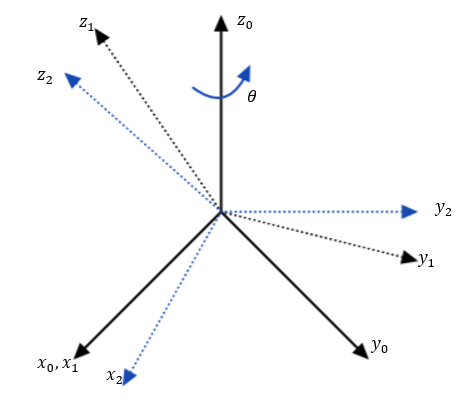

**Figure 2b** - Rotation by $\theta$ about the world z-axis

The third rotation is by an angle of $\varphi$ about the current x-axis, $R_{x,\varphi }$. Since the third rotation is about the currrent frame, the right hand side of equation 1b must be postmultiplied by $R_{x,\varphi }$, see equation 1c. Figure 2c, displays what the third rotation would look like, $x_{3,} y_{3,} z_3$ represents the  new current frame.

$R=R_{z,\theta } R_{x,\phi } R_{x,\varphi } \;=\left\lbrack \begin{array}{ccc}
c\theta  & -s\theta  & 0\\
s\theta  & c\theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & c\phi  & -s\phi \\
0 & s\phi  & c\phi 
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & c\varphi  & -s\varphi \\
0 & s\varphi  & c\varphi 
\end{array}\right\rbrack \;$                                                     (1c)

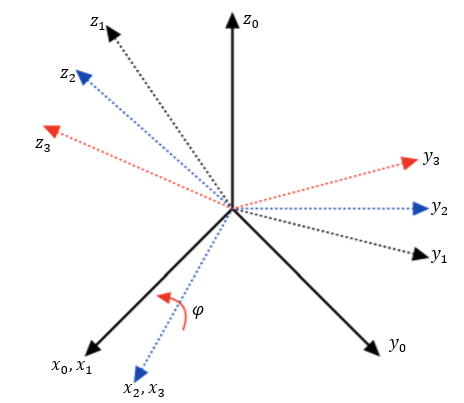

**Figure 2c** - Rotation by $\varphi$ about the current x-axis

The forth rotation is by angle of $\alpha$ about the world z-axis, $R_{z,\alpha }$. Since the forth rotation is about the world frame, the right hand side of equation 1c, must be premultiplied by$R_{z,\alpha }$, see equation 1d. Figure 2a, displays what the first rotation would look like, $x_{1,} y_{1,} z_1$ represents the  new current frame. Figure 2d, displays what the forth rotation would look like, $x_{4,} y_{4,} z_4$ represents the  new current frame.

 $\mathit{\mathbf{R}}={\mathit{\mathbf{R}}}_{\mathit{\mathbf{z}},\alpha } {\mathit{\mathbf{R}}}_{\mathit{\mathbf{z}},\theta } {\mathit{\mathbf{R}}}_{\mathit{\mathbf{x}},\phi } {\mathit{\mathbf{R}}}_{\mathit{\mathbf{x}},\varphi } =\left\lbrack \begin{array}{ccc}
\mathit{\mathbf{c}}\alpha  & -\mathit{\mathbf{s}}\alpha  & 0\\
\mathit{\mathbf{s}}\alpha  & \mathit{\mathbf{c}}\alpha  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
\mathit{\mathbf{c}}\theta  & -\mathit{\mathbf{s}}\theta  & 0\\
\mathit{\mathbf{s}}\theta  & \mathit{\mathbf{c}}\theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \mathit{\mathbf{c}}\phi  & -\mathit{\mathbf{s}}\phi \\
0 & \mathit{\mathbf{s}}\phi  & \mathit{\mathbf{c}}\phi 
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \mathit{\mathbf{c}}\varphi  & -\mathit{\mathbf{s}}\varphi \\
0 & \mathit{\mathbf{s}}\varphi  & \mathit{\mathbf{c}}\varphi 
\end{array}\right\rbrack$                         (1d)

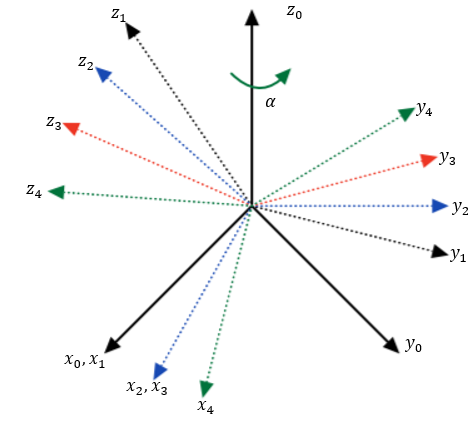

**Figure 2d** - Rotation by $\alpha$ about the world z-axis

**Problem 2 **

Answer:

$H_1^0 =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
0 & 0 & -1 & 0\\
-1 & 0 & 0 & 1\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$**                                                                                                                         (3a)             **

$H_2^0 =\left\lbrack \begin{array}{cccc}
0 & 0 & -1 & 0\\
-1 & 0 & 0 & 1\\
0 & 1 & 0 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$**                                                                                                                         (3b)     **

$H_2^1 =\left\lbrack \begin{array}{cccc}
0 & -1 & 0 & 1\\
0 & 1 & -1 & 0\\
1 & 0 & 0 & -1\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$**                                                                                                                       (3c)     **

$H_2^0 =H_1^0 H_2^1 =\left\lbrack \begin{array}{cccc}
0 & 0 & -1 & 0\\
-1 & 0 & 0 & 1\\
0 & 1 & 0 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                                           ** (6)** 

Problem 2 involves rigid motion. Rigid motion is represents both orientation and position (1). Orientation is represented by the system's rotation matrix and position is represented by the systems position vector.  Homogeneous tranformation matrices are the matrix representation of rigid motion (1). Equation 2.66, in the textbook shows the equation for homogeneous tranformation matrices. 

$H= \left[\matrix{ R & d \cr 0 &1} \right], R\in{SO(3)}, d\in{R^{3}}$                                                                                                           (2.66)

The problem requires the homogeneous transformation matrices $H_1^0 ,H_2^0 ,\textrm{and}\;H_2^1$ to be calculated.  The matrix $H_1^0$, represents the transformations of frame 1 with respect to frame 0. The matrix$H_2^0$, represents the  transformations of frame 2 with respect to frame 0. The matrix $H_2^1$, represents the transformations of frame 2 with respect to frame 1. According to equation 2.66, in order to calculate a homogeneous tranformation matrix both the rotation matrix and position vector of that transformation are needed.  In order to calculate the homogeneous transformation matrix of frame 1 with respect to frame 0,$H_1^0$, both the rotation matrix,$R_1^0$, and the the position vector, $d_1^0$, describing the tranformation of frame 1 with respect to frame 0 are needed, see equation 3a. In a similar fashion the homogeneous tranformation matrices for the other requested frames can be calculated, see equations 3b and 3c.

$H_1^0 =\left\lbrack \begin{array}{cc}
R_1^0  & d_1^0 \\
0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
0 & 0 & -1 & 0\\
-1 & 0 & 0 & 1\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                                    (3a)             

$H_2^0 =\left\lbrack \begin{array}{cc}
R_2^0  & d_2^0 \\
0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
0 & 0 & -1 & 0\\
-1 & 0 & 0 & 1\\
0 & 1 & 0 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                                    (3b)     

$H_2^1 =\left\lbrack \begin{array}{cc}
R_2^1  & d_2^1 \\
0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
0 & -1 & 0 & 1\\
0 & 1 & -1 & 0\\
1 & 0 & 0 & -1\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                                  (3c)     

An easy way to calculate rotation matrices is to compare the coordinate frame vector orientations. Viewing figure 2.13, one may notice that $x_1$ is in the direction opposite of $z_0$, $y_1$is in the direction of $x_0$, and $z_1$ is in the direction opposite of $y_0$. As a result of these frame relations the rotation matrix of frame 1 with respect to frame 0,$R_1^0$, can be calculated, see equation 4a. To calculate the rotation matrix of frame 2 with respect to frame 0, $R_2^0$, we use  the relations that frame $x_1$ is in the direction opposite of $y_0$, $y_1$ is in the direction of $z_0$ and $z_1$ is in the direction opposite of $x_0$, see equation 4b. To calculate the rotation matrix of frame 2 with respect to frame 1, $R_2^1$, we use the relations that frame $x_1$ is in the direction of $z_0$, $y_1$ is in the direction opposite of $x_0$, and $z_1$ is in the direction opposite of $y_0$, see equation 4c.

$R_1^0 =\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & -1\\
-1 & 0 & 0
\end{array}\right\rbrack$                                                                                                                               (4a)                                      

$R_2^0 =\left\lbrack \begin{array}{ccc}
0 & 0 & -1\\
-1 & 0 & 0\\
0 & 1 & 0
\end{array}\right\rbrack$                                                                                                                               (4b)   

$R_2^1 =\left\lbrack \begin{array}{ccc}
0 & -1 & 0\\
0 & 0 & -1\\
1 & 0 & 0
\end{array}\right\rbrack$                                                                                                                               (4c)   

To calculate the position vectors for the different transformations, the displacements of the coordinate frames must be compared for each transformation. From figure 2.13, it is evident that for the transformation from frame 1 to frame 0, $d_1^0$, there was a displacement of 1m in the $z_0$ direction, see equation 5a. For the transformation from frame 2 to frame 0, $d_2^0$, there was a displacement of 1m in the $y_{0\;}$direction, see equation 5b. For the transformation from frame 2 to frame 1, $d_2^1$, there was a displacement of 1m in the $y_0$ direction and a displacement of 1 m in the $-z_0$ direction, see equation 5c. To calculate the three required homogeneous transformation matrixes, $H_1^0 ,H_2^0 ,\textrm{and}\;H_2^1$, equations 4a and 5a are inputted into equation 3a, equations 4b and 5b are inputted into equation 3b and equations 4c and 5c are inputted into equation 3c.

$d_1^0 =\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$                                                                                                                                              (5a) 

$d_2^0 =\left\lbrack \begin{array}{c}
0\\
1\\
0
\end{array}\right\rbrack$                                                                                                                                              (5b) 

$d_1^0 =\left\lbrack \begin{array}{c}
1\\
0\\
-1
\end{array}\right\rbrack$                                                                                                                                           (5c) 

Similar to the rules for the compositions of rotation matrices, see equation 2.22, since the second transformation,$H_2^1$, is performed relative to the current frame, then the previous rotation, $H_1^0$, is postmultiplied by the second transformation, see equation 6. Therefore, the homogeneous transformation matrix produced via equation 3b is the same as the one produced via equation 6.

$H_2^0 =H_1^0 H_2^1 =\left\lbrack \begin{array}{cccc}
0 & 0 & -1 & 0\\
-1 & 0 & 0 & 1\\
0 & 1 & 0 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                                            (6) 

**Problem 3**

Answer:

$H_4^0 =H_1^0$$H_2^1$$H_3^2$$H_4^3$** =**$\left(\begin{array}{cccc}
\mathrm{cos}\left(\theta_1 +\theta_2 \right) & -\mathrm{sin}\left(\theta_1 +\theta_2 \right) & 0 & 275\,\mathrm{cos}\left(\theta_1 -\theta_2 \right)+275\,\mathrm{cos}\left(\theta_1 \right)\\
\mathrm{sin}\left(\theta_1 +\theta_2 \right) & \mathrm{cos}\left(\theta_1 +\theta_2 \right) & 0 & 275\,\mathrm{sin}\left(\theta_1 -\theta_2 \right)-275\,\mathrm{sin}\left(\theta_1 \right)\\
0 & 0 & 1 & d_3 -325\\
0 & 0 & 0 & 1
\end{array}\right)$**                   (9)**

$P_4^0 =$$\left\lbrack \begin{array}{c}
275\,\mathrm{cos}\left(\theta_1 -\theta_2 \right)+275\,\mathrm{cos}\left(\theta_1 \right)\\
275\,\mathrm{sin}\left(\theta_1 -\theta_2 \right)-275\,\mathrm{sin}\left(\theta_1 \right)\\
d_3 -325
\end{array}\right\rbrack$**                                                                                                 (10)**

Problem 3, involves analyzing the Denso's HSR robot 480mm 100 mm z-stroke robot. This is a 3 degree of freedom robot. Using the Denso's catalog (2), the links of the robots were approximated to produce a simplified diagram of the model, see figure 4. The coordinate frames, joint angles and link lengths are labeled. The 0th frame represents the base of the robot which has no joint, the 1st, 2nd and 3rd frames represent the 1st, 2nd and 3rd joints, and the 4th frame represents the end effector.

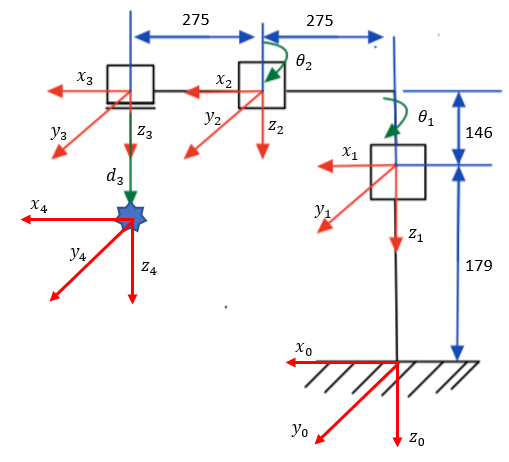

**Figure 4** - Simplified HSR Robot diagram with labeled coordinate frames.

To analyze the system, the homogeneous transformation matrices for the system were calculated using equation 2.66. Like with equations 4a-c, the rotation matrices were calculated by first comparing the frames and then premultiplying the frame rotation matrix by the rotation of the appropriate joint variables in the z direction, equation 2.3. In the system all of the frames are in the same orientation, therefore the first part of the calculation is the identity matrix. Equations 7a - 7d show the rotation matrix calculations for the system. 

$R_1^0 =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$                                                                                                                                   (7a)            

$R_2^1 =\left\lbrack \begin{array}{ccc}
c\theta_1  & -s\theta_1  & 0\\
s\theta_1  & c\theta_1  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
c\theta_1  & -s\theta_1  & 0\\
s\theta_1  & c\theta_1  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$                                                                            (7b)                                                  

$R_3^2 =\left\lbrack \begin{array}{ccc}
c\theta_2  & -s\theta_2  & 0\\
s\theta_2  & c\theta_2  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
c\theta_2  & -s\theta_2  & 0\\
s\theta_2  & c\theta_2  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$                                                                            (7c)    

$R_4^3 =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$                                                                                             (7d)

In the same way that the calculation for the position vectors for problem 2 were calculed in equation 5a-5c, the position vectors for the the HSR robot were calculated, see equation 8a-8d. 

$d_1^0 =$$\left\lbrack \begin{array}{c}
0\\
0\\
-179
\end{array}\right\rbrack$                                                                                                                                       (7a)            

$d_2^1 =$$\left\lbrack \begin{array}{c}
275\cos \theta_1 \\
-275\sin \theta_1 \\
-146
\end{array}\right\rbrack$                                                                                                                                (7b)                                                  

$d_3^2 =$$\left\lbrack \begin{array}{c}
275\cos \theta_2 \\
-275\sin \theta_2 \\
0
\end{array}\right\rbrack$                                                                                                                                (7c)

$d_4^3 =\left\lbrack \begin{array}{c}
0\\
0\\
d_3 
\end{array}\right\rbrack$                                                                                                                                            (7d)

The homogeneous transformation matrices can then be calculated by inputting rotation matrix equation, 6a-6d , the matching postition vector equation, 7a-7d, into equation 2.66. 

$H_1^0 =$$\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & -179\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                                                       (8a)            

$H_2^1 =$$\left\lbrack \begin{array}{cccc}
c\theta_1  & -s\theta_1  & 0 & 275\mathrm{cos}\theta_1 \\
s\theta_1  & c\theta_1  & 1 & -275\mathrm{sin}\theta_1 \\
0 & 0 & 1 & -146\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                                       (8b)                                                  

$H_3^2 =$$\left\lbrack \begin{array}{cccc}
c\theta_2  & -s\theta_2  & 0 & 275\cos \theta_2 \\
s\theta_2  & c\theta_2  & 0 & 275\sin \theta_2 \\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                                          (8c)

$H_4^3 =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & d_3 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                                                             (8d)

Similar to in equation 6, the matrices in equation 8a -8d can be post multiplied sequentially to produce the homogeneos tranformation matrix from the base to end effector, $H_4^0$, see equation 9

$H_4^0 =H_1^0$$H_2^1$$H_3^2$$H_4^3$                                                                                                                                (9)

In order to calculate the position of the robot with different input angles, the 4th colomn of the tranformation matrix can be extracted. This gives the position vector of the system, see equation 10.

$P_4^0 =$$H_4^0$(:,4)$=\left\lbrack \begin{array}{c}
275\,\mathrm{cos}\left(\theta_1 -\theta_2 \right)+275\,\mathrm{cos}\left(\theta_1 \right)\\
275\,\mathrm{sin}\left(\theta_1 -\theta_2 \right)-275\,\mathrm{sin}\left(\theta_1 \right)\\
d_3 -325
\end{array}\right\rbrack$**                                                                                  (10)**

### Results:

#### Problem 1

To represent the rotations in matlab, defined the angle variables as symbolic variables.  By doing this, MATLAB can solve equations without the need for substitution. I then typed the equations of the rotation matrices in terms of the symbolic variables. I then used equation 1d, to multiply the successive rotation matrices in the appropriate order. The code excerpt below symbolically multiplies all of the rotation matrices, in an effort to simplify the resulting matrix. In the code a represents $\alpha$, t represents $\theta$, p represents $\phi$, and z represents $\varphi$. The matrix resulting from the successive rotations is displayed by the code.

The second portion of this assignment problem involved substituting random values for all of the angle variables. For portion my random values are as follows:


$$\alpha =25\circ$$
 


$$\theta =20\circ \;$$



$$\phi =30\circ$$
 


$$\varphi =45\circ$$


The resulting matrix from the successive ratations, describe by the problem statement, by the angles  that I defined above is displayed by the code.

clear; clc;
syms a t p z
ra= [cos(a) -sin(a) 0;sin(a) cos(a) 0;0 0 1];
rt =[cos(t) -sin(t) 0;sin(t) cos(t) 0;0 0 1];
rp =[1 0 0; 0 cos(p) -sin(p);0 sin(p) cos(p)];
rz =[1 0 0; 0 cos(z) -sin(z);0 sin(z) cos(z)];
R= ra*rt*rp*rz;
R_simple= simplify (R)

$$R\_simple = \left(\begin{array}{ccc} \cos\left(a+t\right) & -\sin\left(a+t\right)\,\cos\left(p+z\right) & \sin\left(a+t\right)\,\sin\left(p+z\right)\\ \sin\left(a+t\right) & \cos\left(a+t\right)\,\cos\left(p+z\right) & -\cos\left(a+t\right)\,\sin\left(p+z\right)\\ 0 & \sin\left(p+z\right) & \cos\left(p+z\right) \end{array}\right)$$

answer = subs (R, [p,t,z,a], [deg2rad(30),deg2rad(20),deg2rad(45),deg2rad(25)]);
R_subbed= simplify (answer)

$$R\_subbed = \left(\begin{array}{ccc} \frac{\sqrt{2}}{2} & \frac{1}{4}-\frac{\sqrt{3}}{4} & \frac{\sqrt{3}}{4}+\frac{1}{4}\\ \frac{\sqrt{2}}{2} & \frac{\sqrt{3}}{4}-\frac{1}{4} & -\frac{\sqrt{3}}{4}-\frac{1}{4}\\ 0 & \frac{\sqrt{2}}{4}+\frac{\sqrt{6}}{4} & \frac{\sqrt{6}}{4}-\frac{\sqrt{2}}{4} \end{array}\right)$$

Below is the simplified representation of the resulting matrix

### 
$$R=\;\left(\begin{array}{ccc}
\cos \left(\alpha +\theta \right) & -\sin \left(\alpha +\theta \right)\,\cos \left(\phi +\varphi \right) & \sin \left(\alpha +\theta \right)\,\sin \left(\phi +\varphi \right)\\
\sin \left(\alpha +\theta \right) & \cos \left(\alpha +\theta \right)\,\cos \left(\phi +\varphi \right) & -\cos \left(\alpha +\theta \right)\,\sin \left(\phi +\varphi \right)\\
0 & \sin \left(\phi +\varphi \right) & \cos \left(\phi +\varphi \right)
\end{array}\right)$$


Below is the resulting rotation matrix when the I inputted the angle variables that I specified.


$$R\left(30,20,45,25\right)=\left(\begin{array}{ccc}
\frac{\sqrt{2}}{2} & \frac{1}{4}-\frac{\sqrt{3}}{4} & \frac{\sqrt{3}}{4}+\frac{1}{4}\\
\frac{\sqrt{2}}{2} & \frac{\sqrt{3}}{4}-\frac{1}{4} & -\frac{\sqrt{3}}{4}-\frac{1}{4}\\
0 & \frac{\sqrt{2}}{4}+\frac{\sqrt{6}}{4} & \frac{\sqrt{6}}{4}-\frac{\sqrt{2}}{4}
\end{array}\right)$$


#### Problem 2

Below are the calculations of the desired homogeneous tranformation matrices, $H_1^0 ,H_2^0 ,\textrm{and}\;H_2^1$

Using equation 6, $H_2^0$ is calculated again. 

l01= 1;
l02 =1;
l12= sqrt(2);

R01= [0 1 0; 0 0 -1; -1 0 0];
d01= [0;0;1];
R02= [0 0 -1;-1 0 0; 0 1 0];
d02= [0;1;0];
R12= [0 -1 0;0 0 -1;1 0 0];
d12= [1;0;-1];

H01= [R01 d01; 0 0 0 1]

H01 =      0     1     0     0
     0     0    -1     0
    -1     0     0     1
     0     0     0     1


H02= [R02 d02; 0 0 0 1]

H02 =      0     0    -1     0
    -1     0     0     1
     0     1     0     0
     0     0     0     1


H12= [R12 d12; 0 0 0 1]

H12 =      0    -1     0     1
     0     0    -1     0
     1     0     0    -1
     0     0     0     1



H02_ver= H01*H12

H02_ver =      0     0    -1     0
    -1     0     0     1
     0     1     0     0
     0     0     0     1


#### Problem 3:

Denso's HSR robot homogeneous tranformation matrix calculation. I then extracted the 4th column of the tranformation matrix and plotted it with the given ranges in order to analyze it's path.

syms q1 q2 q3 

% define link lengths
l1= 179;
l2= 146;
l3= 275;
l4= 275;

R01= [1 0 0 ; 0 1 0; 0 0 1];
d01= [0;0;-l1];
H01= [R01 d01; 0 0 0 1];
% all of the trig function take degrees 

R12= [cosd(q1) -sind(q1) 0; sind(q1) cosd(q1) 0; 0 0 1];
d12= [l3*cosd(q1); -l3*sind(q1);-l2];
H12= [R12 d12; 0 0 0 1];
R23= [cosd(q2) -sind(q2) 0; sind(q2) cosd(q2) 0; 0 0 1];
d23= [l4*cosd(q2); -l4*sind(q2);0];
H23= [R23 d23; 0 0 0 1];
R34= [1 0 0;  0 1 0; 0 0 1];
d34= [0 ; 0 ; q3];
H34= [R34 d34; 0 0 0 1];

%{
R12= [cos(q1) -sin(q1) 0; sin(q1) cos(q1) 0; 0 0 1];
d12= [l3*cos(q1); -l3*sin(q1);-l2];
H12= [R12 d12; 0 0 0 1];
R23= [cos(q2) -sin(q2) 0; sin(q2) cos(q2) 0; 0 0 1];
d23= [l4*cos(q2); -l4*sin(q2);0];
H23= [R23 d23; 0 0 0 1];
R34= [1 0 0;  0 1 0; 0 0 1];
d34= [0 ; 0 ; q3];
H34= [R34 d34; 0 0 0 1];
%}

H04= H01*H12*H23*H34;
H04_simp=simplify(H04)

$$H04\_simp = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & 275\,\cos\left(\frac{\pi \,q_{1}}{180}\right)+275\,\cos\left(\frac{\pi \,\left(q_{1}-q_{2}\right)}{180}\right)\\ \sigma_{1} & \sigma_{2} & 0 & 275\,\sin\left(\frac{\pi \,\left(q_{1}-q_{2}\right)}{180}\right)-275\,\sin\left(\frac{\pi \,q_{1}}{180}\right)\\ 0 & 0 & 1 & q_{3}-325\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,\left(q_{1}+q_{2}\right)}{180}\right)\\ \sigma_{2}=\cos\left(\frac{\pi \,\left(q_{1}+q_{2}\right)}{180}\right) \end{array}$$


q1t= 0:1:180;
q2t= 0:1/2:90;
q3t= 0:(100/180):100;

pe = expand(H04(1:3,4));
pe_simp= simplify(pe)

$$pe\_simp = \left(\begin{array}{c} 275\,\cos\left(\frac{\pi \,q_{1}}{180}\right)+275\,\cos\left(\frac{\pi \,\left(q_{1}-q_{2}\right)}{180}\right)\\ 275\,\sin\left(\frac{\pi \,\left(q_{1}-q_{2}\right)}{180}\right)-275\,\sin\left(\frac{\pi \,q_{1}}{180}\right)\\ q_{3}-325 \end{array}\right)$$

%[qq1,qq2,qq3]=meshgrid (q1t,q2t,q3t);

x=pe_simp(1)

$$x = 275\,\cos\left(\frac{\pi \,q_{1}}{180}\right)+275\,\cos\left(\frac{\pi \,\left(q_{1}-q_{2}\right)}{180}\right)$$

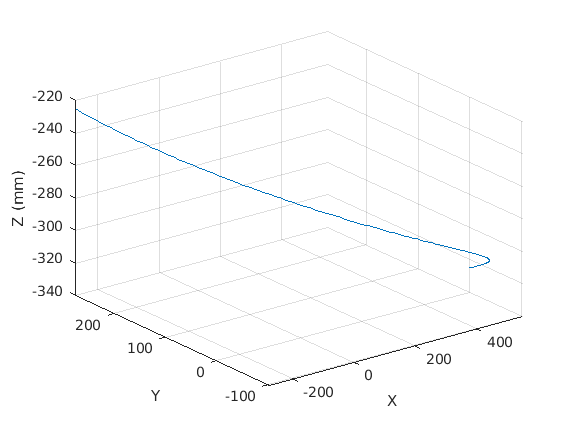

y=pe_simp(2);
z=pe_simp(3);

x_plot= subs(x,{q1 q2 q3},{q1t q2t q3t});
%simplify(x_plot)
y_plot= subs(y,{q1 q2 q3},{q1t q2t q3t});
z_plot=subs(z,{q1 q2 q3},{q1t q2t q3t});

plot3(x_plot,y_plot,z_plot)
grid on
xlabel('X ')
ylabel('Y ')
zlabel('Z (mm)')

**Figure 5** - Path of HSR robot

### Discussion:

The first problem of this assignment was very straight forward, it involved implementing the rules of composition of rotations. Once I identified which of the rotations were about the current frame and which were about the fixed frame, i was able to produce the appropriate rotation matrix multiplation order inorder to correctly represent the system. 

The second problem of the assignemnt straight forward, and was actually my favorite of the assignment. In this problem, I was able to calculate the homogeneous transformation matrices that were required by the problem and at the same time, I was provided with a hint at how I could check my work for errors, using equation 6. After calculating the tranformation matrices using equation 2.66, I was able to reproduce the the same homogeneous matrix that represents the tranformation of frame 2 with respect to frame 1, $H_2^0$, using equation 6. The fact that the matrices match show that my calculations was probably correct.

the thrid problem of this assignment, involved analyzing and creating my own model of the HSR robot. This problem was very challenging and fun, since it allowed me to analyze a real world robot with the equations and knowledge that I have aquired through this class. I represented the robot as 3 degree of freedom robot that has four frames. It has two revolute joints and 1 prismatic joint. I represented the base as the 0th frame or  the origin; the 1st frame represented the first joint of the robot; the 2nd frame represent the second joint; the 3rd joint represented the 3rd joint and thd the 3th joint represented the end effector. To analyze this robot I calculated the successive rotation matrices and postion vectors for each frame and then used them to calculate the homogenouse rotation matrix from the base of the robot to the end effector. I then extracted the position vector from the tranformation matrix and plotted it with the given joint values. Figure 5, displays the resulting plot. The plot displays postion of the end effector relative to the base. The base of the robot is fixed, the joints of the robot cause the end effector's position to change. The plot looks as expected;  since joint 1 and 2 are steadily increasing, it is expected that the end effector would loop inward once it reaches the higer angles, as it is seen doing in the lower right portion of the plot. It can be noticed that the the z axis of the plot is negative, this is due to the fact that I defined the down direction as the positive z direction. As joint 3 increases from 0mm to 100mm, the z position of the end effector lowers or reduces. This was to be expected because as the joint 3 variable increased the position of the end effector gets closer to the height of the base because it is getting lower. 

### References:

(1) Spong et al. (2020).* Robot Modeling and Control *(2nd Edition). Wiley.

(2) Denso. *HSR Series: 480-650mm*. Retrieved from: [https://html5.dcatalog.com/?docid=72c75621-8544-41b4-9afa-a7f60153efbd&page=32.](https://html5.dcatalog.com/?docid=72c75621-8544-41b4-9afa-a7f60153efbd&page=32.) 